## BASIC IMAGE OPERATIONS

### Color channels

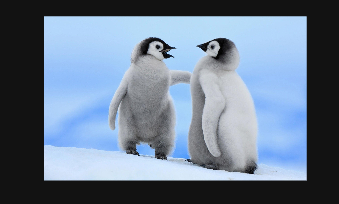

I0 = imread("images/pengu.jpg");
imshow(I0)

size(I0)

ans =         1800        2880           3


max(max(I0))

ans = 1×1×3 uint8 array
ans(:,:,1) =

   242


ans(:,:,2) =

   248


ans(:,:,3) =

   255


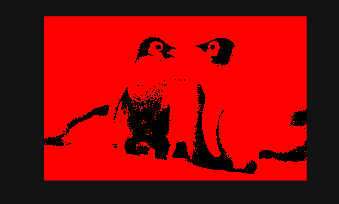

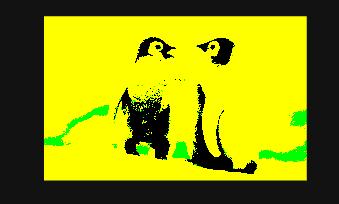

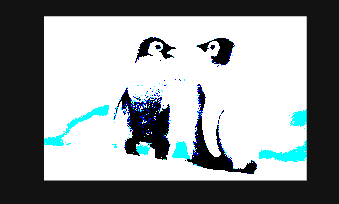

I = I0/255;
I_col = zeros(size(I));

for i = 1:3
    I_col(:, :, i) = I(:, :, i);
    figure
    imshow(I_col);
end


figure

### Image Conversion

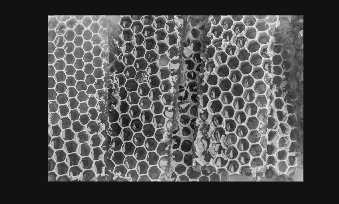


I1 = imread("images/honey-comb.jpg");
imshow(rgb2gray(I1))

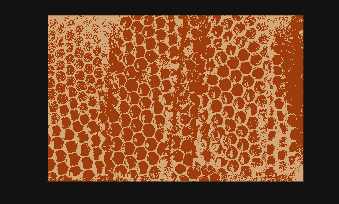

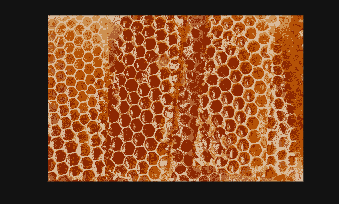

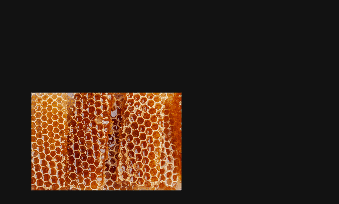

for i = [2 5 50]
    [X, map] = rgb2ind(I1, i);
    figure; imshow(X, map)
end

### Sampling

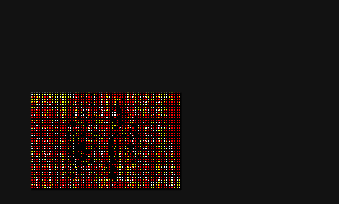

[r, c, s] = size(I1);
N = 2;
I1s = I1/255;
y = zeros(size(I1s));
y(1:N:r, 1:N:c, :) = I1s(1:N:r, 1:N:c, :);
imshow(y)

### Noisy Image

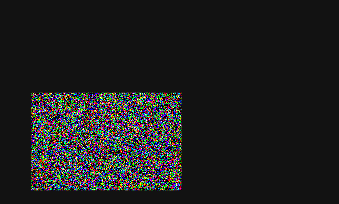

imshow(imnoise(I1s, "gaussian", 0, 1));

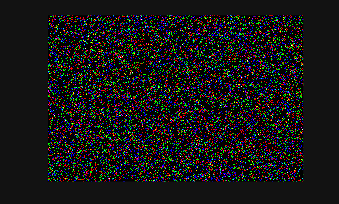

imshow(imnoise(I1s, "salt & pepper", 0.19));

### Bit Resolution

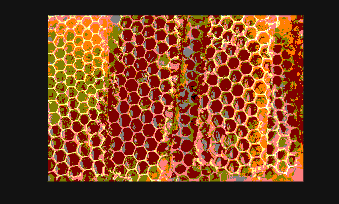

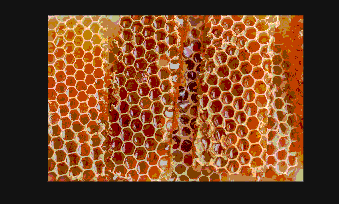

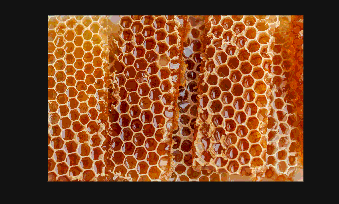


b = [7 6 5];
for i = 1 : length(b)
    d = 2^b(i);
    z = round(I1/d);
    figure
    imshow(z*d)
end